# Control and Instrumentation Lab Assignment 6

**SWARNENDU PAUL 19EE3FP18**

## Bode and Nyquist Plots

**Question 3.**

**a,b.**

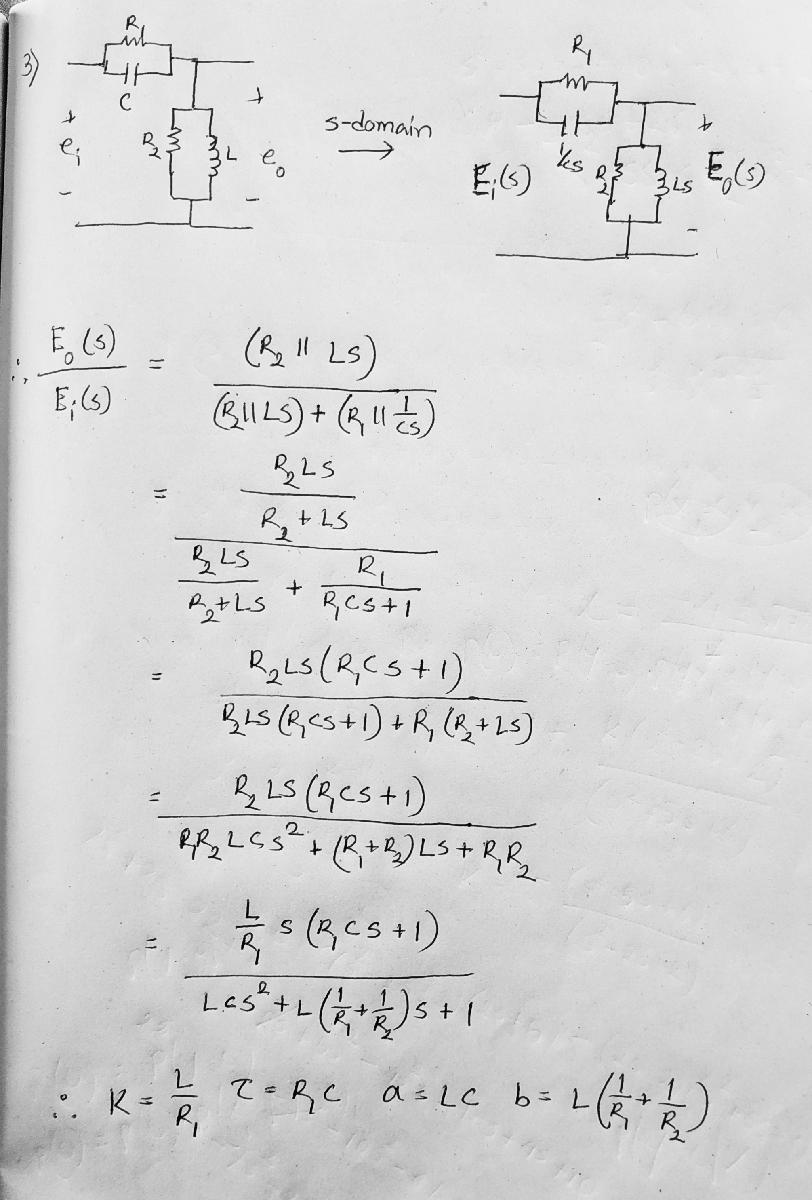

**c.**

Given values, $R_1=100\Omega$, $R_2=500\Omega$, $L=1mH$, $C=200\mu F$

Hence $K=1\times 10^{-5}$, $\tau=0.02$, $a=2\times10^{-7}$, $b=1.2\times10^{-5}$

k=1e-5;
t=0.02;
a=2e-7;
b=1.2e-5;
G=tf([k*t,k,0],[a,b,1])

G =
 
     2e-07 s^2 + 1e-05 s
  -------------------------
  2e-07 s^2 + 1.2e-05 s + 1
 
Continuous-time transfer function.



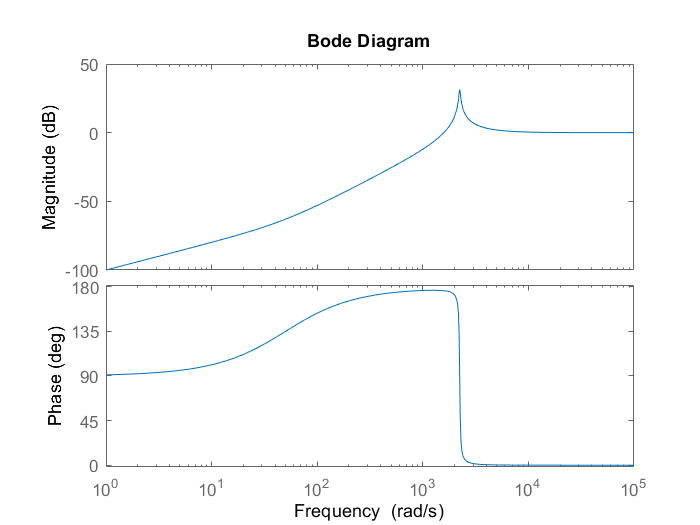

bode(G)

From the bodeplot, we can conclude, the system acts as a high-pass filter. As the phase never crosses $-180^\circ$ so, we cannot calculate gain margin. There is a point before the resonant peak where the gain becomes equal to 1. Hence we can calculate phase margin and gain crossover frequency using MATLAB

allmargin(G)

ans = struct with fields:
     GainMargin: [1×0 double]
    GMFrequency: [1×0 double]
    PhaseMargin: [-3.9847 -180]
    PMFrequency: [1.5812e+03 Inf]
    DelayMargin: [0.0039 0]
    DMFrequency: [1.5812e+03 Inf]
         Stable: 1


So at $\omega=1.5812\times10^3$ the gain becomes 1(Gain crossover frequency), and the phase margin is equal to $-3.9847^\circ$.

**Question 4.**

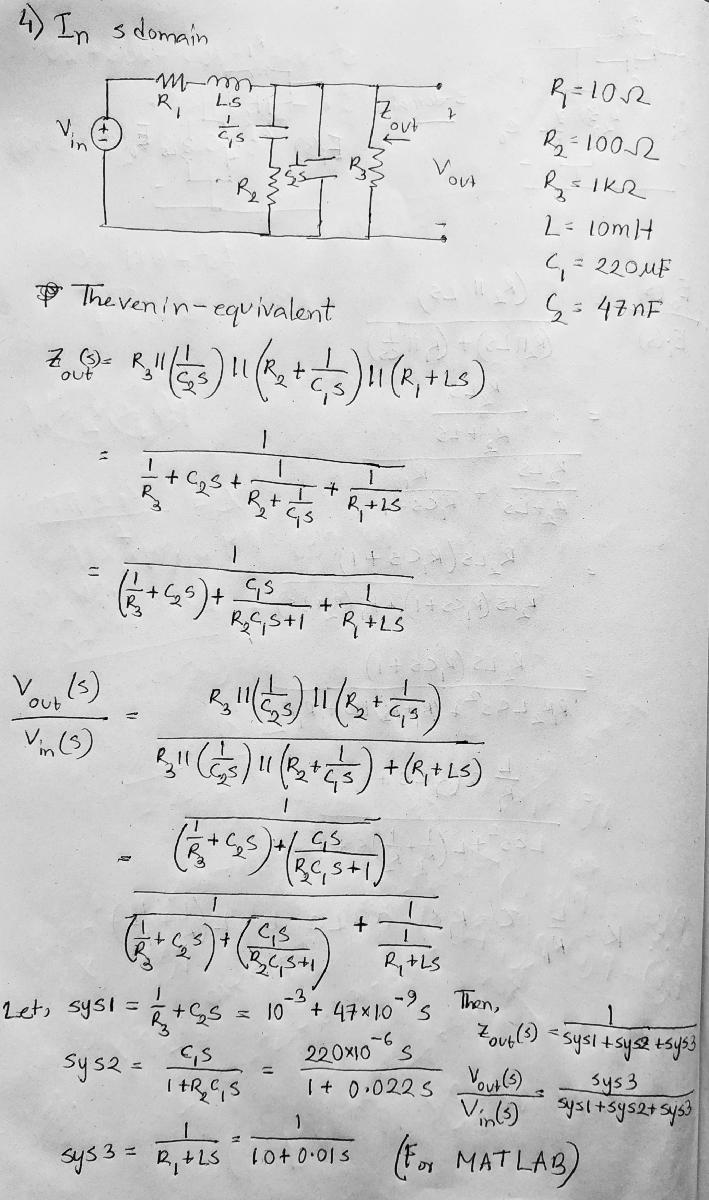

sys1=tf([47e-9,1e-3],1);
sys2=tf([220e-6,0],[0.022,1]);
sys3=tf(1,[0.01,10]);
Zout=1/(sys1+sys2+sys3)

Zout =
 
             0.00022 s^2 + 0.23 s + 10
  ------------------------------------------------
  1.034e-11 s^3 + 2.431e-06 s^2 + 0.02443 s + 1.01
 
Continuous-time transfer function.



H=sys3/(sys1+sys2+sys3) %Vo/Vin

H =
 
                     0.00022 s^2 + 0.23 s + 10
  ---------------------------------------------------------------
  1.034e-13 s^4 + 2.441e-08 s^3 + 0.0002686 s^2 + 0.2544 s + 10.1
 
Continuous-time transfer function.



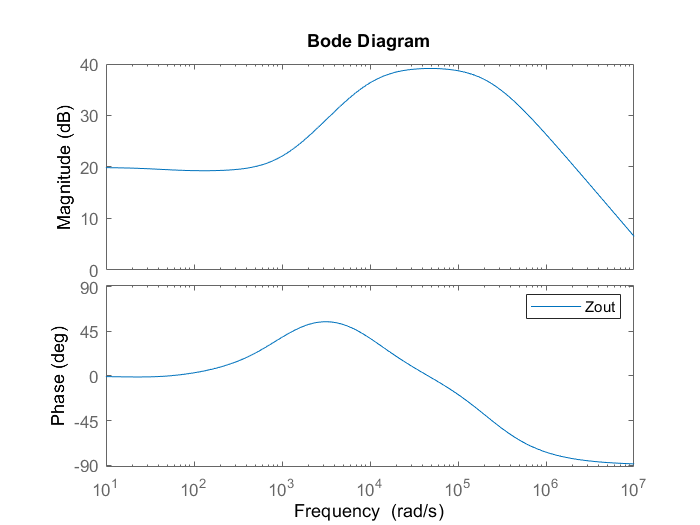

bode(Zout)
legend

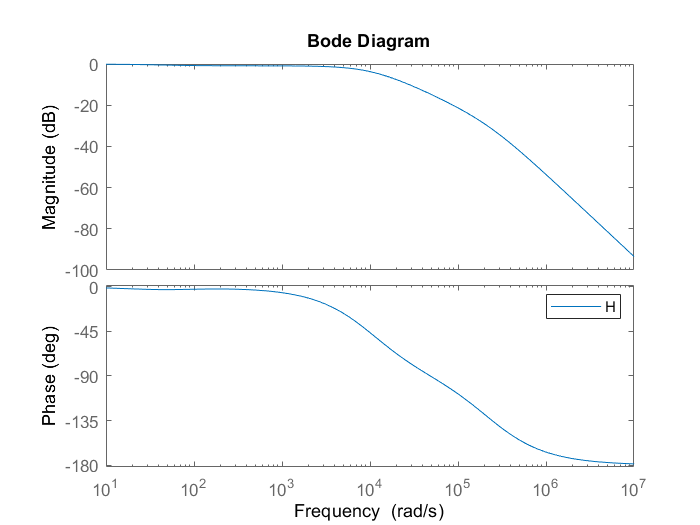

bode(H)
legend

From the bode plot we can conclude that, the circuit works as a low-pass filter. 

To find the corner frequency we can use the matlab 'bandwidth' function.

bandwidth(H)

ans = 8.5241e+03

Hence corner frequency of the low-pass filter(-3dB frequency) = **8524.1 rad/sec **= **1.357KHz**